# **LiDAR SLAM**

addpath('./functions');

## Tracciamento della traiettoria

### Definizione della scena 

sceneName = 'LargeParkingLot';
[sceneImage, sceneRef] = helperGetSceneImage(sceneName);

### Selezione manuale dei waypoints

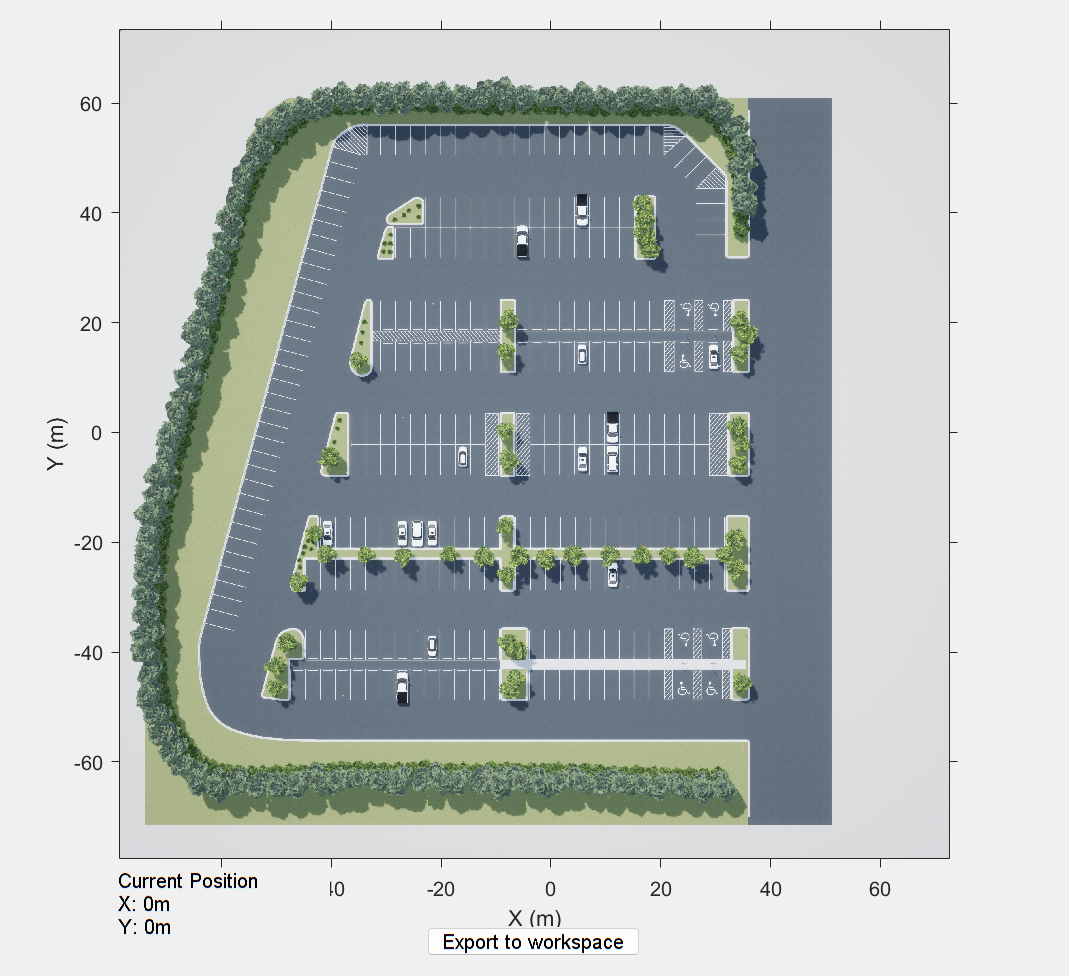

hFig = helperSelectSceneWaypoints(sceneImage, sceneRef);

### Genera percorso continuo 

numPoses = size(refPoses{1}, 1);
refDirections  = ones(numPoses,1);   % Movimento in avanti
numSmoothPoses = 20 * numPoses;      % Aumenta la densità delle pose

[smoothRefPoses,~,cumLengths] = smoothPathSpline(refPoses{1}, refDirections, numSmoothPoses);

## Simulazione

modelName = 'CustomLidarSLAM';
open_system(modelName);

% Parametri
simStopTime = 10;
set_param(modelName, 'StopTime', num2str(simStopTime));

timeVector = normalize(cumLengths, 'range', [0, simStopTime]);

% Variabili per Simulink
refPosesX = [timeVector, smoothRefPoses(:,1)];
refPosesY = [timeVector, smoothRefPoses(:,2)];
refPosesT = [timeVector, smoothRefPoses(:,3)];

### Estrazione dei dati LIDAR

lidarData = out.lidarScans.signals.values;  
numScans = size(lidarData, 4); % Numero totale di scansioni nel tempo

### Visualizzazione della scansione

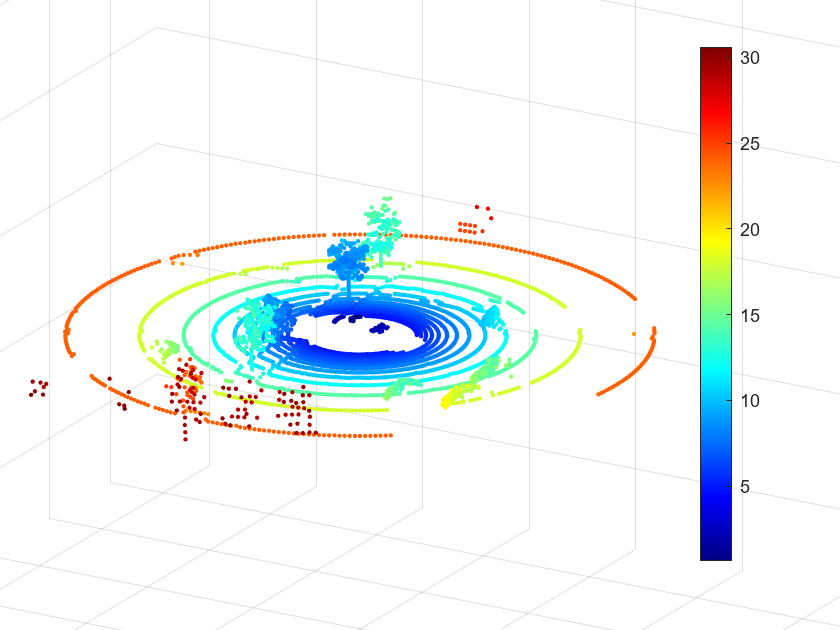

% Creazione della finestra di visualizzazione
figure;
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Nuvola di punti LIDAR in tempo reale');
axis equal;
grid on;
colormap jet; % Imposta la mappa di colori per la distanza
view(30, 20); % Imposta la vista isometrica
camzoom(2); % Aumenta il fattore per avvicinarti di più

lidarValues = squeeze(lidarData(:, :, :, 1)); % (32x360x3) -> (N x 3)
points3D = reshape(lidarValues, [], 3); % Trasforma in (32*360, 3)

% Calcola la distanza dall'origine per ogni punto
distances = sqrt(sum(points3D.^2, 2)); 

% Creazione dell'oggetto scatter per aggiornamenti in tempo reale
scatterHandle = scatter3(points3D(:, 1), points3D(:, 2), points3D(:, 3), 5, distances, 'filled');
colorbar; % Aggiunge una legenda per il colore basato sulla distanza

% Loop per aggiornare la visualizzazione senza errori
for scanIndex = 2:numScans  
    lidarValues = squeeze(lidarData(:, :, :, scanIndex)); % (32x360x3)  
    points3D = reshape(lidarValues, [], 3); % (32*360, 3)

    % Calcola la distanza dall'origine
    distances = sqrt(sum(points3D.^2, 2)); 

    % Aggiorna la nuvola di punti con colore basato sulla distanza
    set(scatterHandle, 'XData', points3D(:, 1), ...
                       'YData', points3D(:, 2), ...
                       'ZData', points3D(:, 3), ...
                       'CData', distances); % Colore basato sulla distanza
    drawnow;
end

%hMapOnScene = helperSuperImposeMapOnSceneImage('LargeParkingLot',
%points3D); % da rivedere 

## Preprocessing dati LiDAR

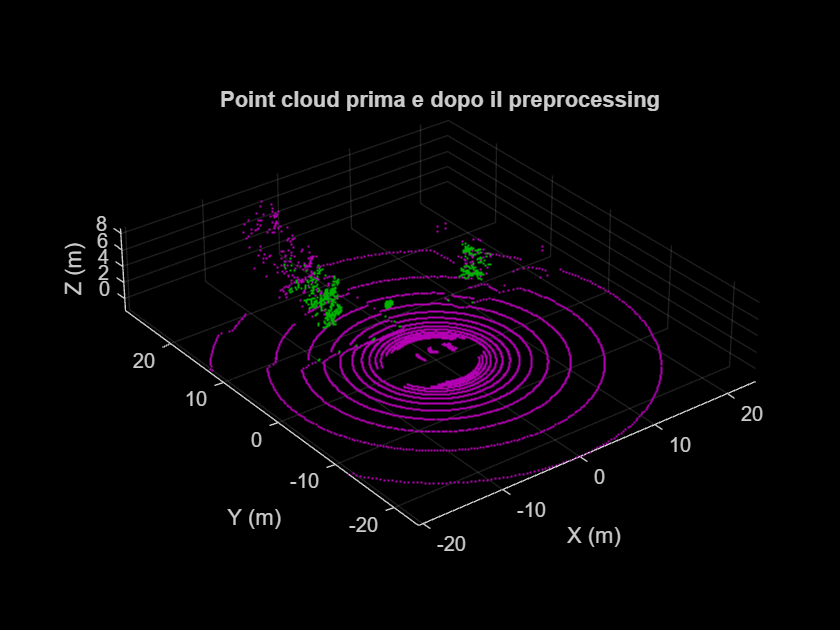

% Extract lidar data
ptCloudArr = helperPointClouds(out);


% Extract ground truth for the lidar data as an array of rigidtform3d objects
groundTruthPosesLidar = helperGetLidarGroundTruth(out);

ptCloud = ptCloudArr(1);

% Use the helper function to preprocess the point cloud
ptCloudProcessed = helperPreprocessPC(ptCloud);

% Visualize and compare the point cloud before and after preprocessing.
figure(Name="Processed Point Clouds",NumberTitle="off");
pcViewAxes = pcshowpair(ptCloud, ptCloudProcessed);
title("Point cloud prima e dopo il preprocessing");
xlabel(pcViewAxes,"X (m)");
ylabel(pcViewAxes,"Y (m)");
zlabel(pcViewAxes,"Z (m)");

## Costruzione della Mappa 3D (Dati Processati)

Frame 1 of 100
Frame 2 of 100
Frame 3 of 100
Frame 4 of 100
Frame 5 of 100
Frame 6 of 100
Frame 7 of 100
Frame 8 of 100
Frame 9 of 100
Frame 10 of 100
Frame 11 of 100
Frame 12 of 100
Frame 13 of 100
Frame 14 of 100
Frame 15 of 100
Frame 16 of 100
Frame 17 of 100
Frame 18 of 100
Frame 19 of 100
Frame 20 of 100
Frame 21 of 100
Frame 22 of 100
Frame 23 of 100
Frame 24 of 100
Frame 25 of 100
Frame 26 of 100
Frame 27 of 100
Frame 28 of 100
Frame 29 of 100
Frame 30 of 100
Frame 31 of 100
Frame 32 of 100
Frame 33 of 100
Frame 34 of 100
Frame 35 of 100
Frame 36 of 100
Frame 37 of 100
Frame 38 of 100
Frame 39 of 100
Frame 40 of 100
Frame 41 of 100
Frame 42 of 100
Frame 43 of 100
Frame 44 of 100
Frame 45 of 100
Frame 46 of 100
Frame 47 of 100
Frame 48 of 100
Frame 49 of 100
Frame 50 of 100
Frame 51 of 100
Frame 52 of 100
Frame 53 of 100
Frame 54 of 100
Frame 55 of 100
Frame 56 of 100
Frame 57 of 100
Frame 58 of 100
Frame 59 of 100
Frame 60 of 100
Frame 61 of 100
Frame 62 of 100
Frame 63 of 100
F

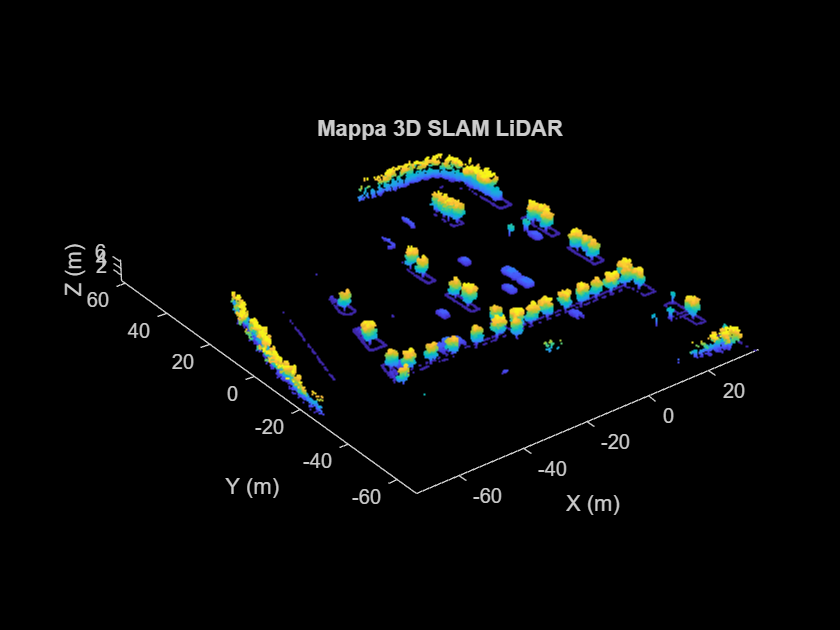

% Inizializzazione della mappa 3D
map3D = pointCloud(zeros(0,3));

% Numero di scansioni
numFrames = numel(ptCloudArr);

% Ciclo sulle scansioni e accumulo nella mappa
for frameIdx = 1:numFrames
    disp("Frame " + frameIdx + " of " + numFrames);
    
    % Estrai la scansione corrente e la posa associata
    ptCloud = ptCloudArr(frameIdx);
    ptCloudProcessed = helperPreprocessPC(ptCloud);
    
    pose = groundTruthPosesLidar(frameIdx); % rigidtform3d

    % Applica la trasformazione alla scansione
    transformedPtCloud = pctransform(ptCloudProcessed, pose);

    % Aggiungi la scansione trasformata alla mappa
    map3D = pcmerge(map3D, transformedPtCloud, 0.05); % Fusione con risoluzione 5 cm

    % Visualizza la mappa aggiornata
    clf; % Pulisce la figura per aggiornamenti fluidi
    pcshow(map3D);
    title("Mappa 3D SLAM LiDAR");
    grid off;
    axis on;
    xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");
    view(3);
    drawnow;
end

## Costruzione della Mappa 3D (Dati RAW) - Opzionale

Frame 1 of 100
Frame 2 of 100
Frame 3 of 100
Frame 4 of 100
Frame 5 of 100
Frame 6 of 100
Frame 7 of 100
Frame 8 of 100
Frame 9 of 100
Frame 10 of 100
Frame 11 of 100
Frame 12 of 100
Frame 13 of 100
Frame 14 of 100
Frame 15 of 100
Frame 16 of 100
Frame 17 of 100
Frame 18 of 100
Frame 19 of 100
Frame 20 of 100
Frame 21 of 100
Frame 22 of 100
Frame 23 of 100
Frame 24 of 100
Frame 25 of 100
Frame 26 of 100
Frame 27 of 100
Frame 28 of 100
Frame 29 of 100
Frame 30 of 100
Frame 31 of 100
Frame 32 of 100
Frame 33 of 100
Frame 34 of 100
Frame 35 of 100
Frame 36 of 100
Frame 37 of 100
Frame 38 of 100
Frame 39 of 100
Frame 40 of 100
Frame 41 of 100
Frame 42 of 100
Frame 43 of 100
Frame 44 of 100
Frame 45 of 100
Frame 46 of 100
Frame 47 of 100
Frame 48 of 100
Frame 49 of 100
Frame 50 of 100
Frame 51 of 100
Frame 52 of 100
Frame 53 of 100
Frame 54 of 100
Frame 55 of 100
Frame 56 of 100
Frame 57 of 100
Frame 58 of 100
Frame 59 of 100
Frame 60 of 100
Frame 61 of 100
Frame 62 of 100
Frame 63 of 100
F

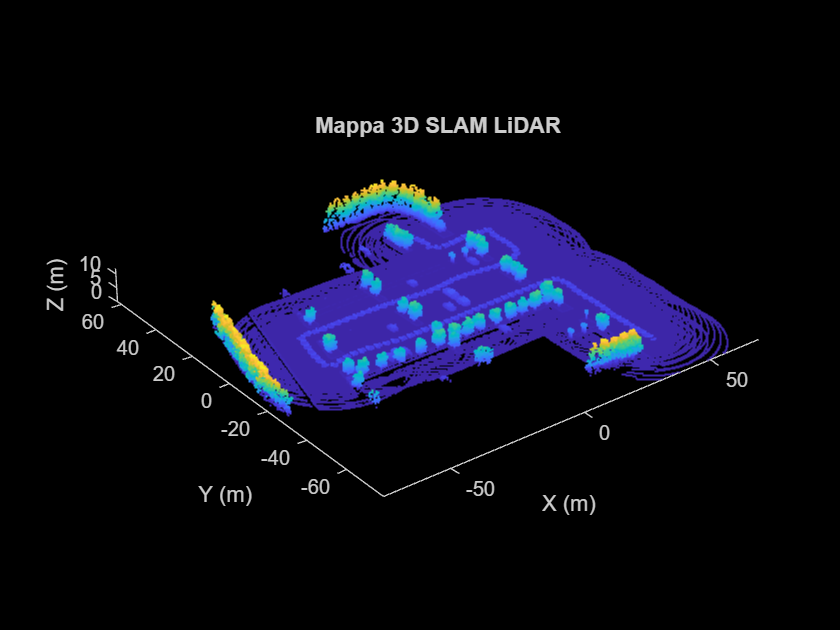

% Inizializzazione della mappa 3D
map3D = pointCloud(zeros(0,3));

% Numero di scansioni
numFrames = numel(ptCloudArr);

% Ciclo sulle scansioni e accumulo nella mappa
for frameIdx = 1:numFrames
    disp("Frame " + frameIdx + " of " + numFrames);
    
    % Estrai la scansione corrente e la posa associata
    ptCloud = ptCloudArr(frameIdx);
    pose = groundTruthPosesLidar(frameIdx); % rigidtform3d

    % Applica la trasformazione alla scansione
    transformedPtCloud = pctransform(ptCloud, pose);

    % Aggiungi la scansione trasformata alla mappa
    map3D = pcmerge(map3D, transformedPtCloud, 0.05); % Fusione con risoluzione 5 cm

    % Visualizza la mappa aggiornata
    clf; % Pulisce la figura per aggiornamenti fluidi
    pcshow(map3D);
    title("Mappa 3D SLAM LiDAR");
    grid on;
    axis on;
    xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");
    view(3);
    drawnow;
end